% Note:
% 1. Start by running the first section (data preprocessing) to set up the dataset.
% 2. After preprocessing, choose the relevant task (e.g., Task 2b or Task 2d) and execute it separately.
% 3. Do not attempt to run the entire script at once, as the tasks are independent and require preprocessing first.

%% Clear environment
clc;
clear all;

%% Set the random seed for reproducibility
rng(0);

%% Read the Iris dataset
filename = 'IrisData.txt';  
data = readtable(filename, 'Delimiter', ',', 'ReadVariableNames', false);
% The data has 5 columns: first 4 columns are features, the 5th column is the label.

numericData = data(:, 1:4);          % Extract the first 4 columns of numerical features
label_data = data(:, 5);            % Extract the 5th column as labels
labels = zeros(height(data), 3);     % We will use a 150x3 matrix for one-hot encoding (3 classes)

%% Convert string labels to one-hot encoding
correct_label = 1;
incorrect_label = 0;

setosa_index = find(strcmp(data{:, 5}, 'Iris-setosa'));
versicolor_index = find(strcmp(data{:, 5}, 'Iris-versicolor'));
virginica_index = find(strcmp(data{:, 5}, 'Iris-virginica'));

% For each row, only the correct class is 1, the others are 0
labels(setosa_index, 1) = correct_label;
labels(setosa_index, 2:3) = incorrect_label;

labels(versicolor_index, 1) = incorrect_label;
labels(versicolor_index, 2) = correct_label;
labels(versicolor_index, 3) = incorrect_label;

labels(virginica_index, 1:2) = incorrect_label;
labels(virginica_index, 3) = correct_label;

%% Shuffle the dataset randomly and split into 70% training data and 30% validation data
numSamples = size(data, 1);                  % total number of samples, e.g., 150
randomIndices = randperm(numSamples);        % random permutation of sample indices
numTrainSamples = round(0.7 * numSamples);   % 70% for training
trainIndices = randomIndices(1:numTrainSamples);
testIndices = randomIndices(numTrainSamples+1:end);

% Training and validation features
trainData = numericData(trainIndices, :);
validationData = numericData(testIndices, :);

% Training and validation labels
trainLabels = labels(trainIndices, :);
validationLabels = labels(testIndices, :);

% Convert table to array for matrix computations
trainData = table2array(trainData);
validationData = table2array(validationData);


%% ----------------- Task 2 b) Handwritten forward + backward propagation (Gradient Descent) -----------------
% Network architecture and training parameters
inputLayerSize = 4;      % number of input neurons (Iris has 4 features)
hiddenLayer1Size = 5;    % number of neurons in the first hidden layer
hiddenLayer2Size = 3;    % number of neurons in the second hidden layer
outputLayerSize = 3;     % number of output neurons (3 classes)
learningRate = 0.01;     % learning rate
epochs = 700;           % number of training iterations

% Randomly initialize weights and biases
W1 = randn(inputLayerSize, hiddenLayer1Size);
B1 = randn(1, hiddenLayer1Size);

W2 = randn(hiddenLayer1Size, hiddenLayer2Size);
B2 = randn(1, hiddenLayer2Size);

W3 = randn(hiddenLayer2Size, outputLayerSize);
B3 = randn(1, outputLayerSize);

% Define the activation function (tanh), its derivative, and softmax
tanhActivation = @(x) tanh(x);
dtanh = @(x) 1 - tanh(x).^2;
softmax = @(x) exp(x) ./ sum(exp(x)); % softmax along each row

% Arrays to store the loss values for both training and validation
loss_values = zeros(epochs, 1);
validation_loss_values = zeros(epochs, 1);

%% Train the network (sample-by-sample update)
for epoch = 1:epochs
    total_train_loss = 0;     % accumulate training loss for averaging

    for i = 1:numTrainSamples
        %% Forward pass (single sample)
        x = trainData(i, :)';      % current sample features (column vector)
        y = trainLabels(i, :)';    % current sample one-hot label (column vector)
        
        % 1st hidden layer
        Z1 = W1' * x + B1';          % W1 is [4 x 5], so W1' is [5 x 4]
        A1 = tanhActivation(Z1);     % output shape [5 x 1]
        
        % 2nd hidden layer
        Z2 = W2' * A1 + B2';
        A2 = tanhActivation(Z2);     % output shape [3 x 1]
        
        % Output layer
        Z3 = W3' * A2 + B3';
        A3 = softmax(Z3);           % output shape [3 x 1]
        
        % Compute training loss (MSE for classification as an example)
        error = A3 - y;
        total_train_loss = total_train_loss + sum(error.^2) / numel(error);
        
        %% Backpropagation for gradient computation
        % Gradients in output layer
        dZ3 = error;                   % shape [3 x 1]
        dW3 = A2 * dZ3';               % shape [3 x 3] -> consistent with W3
        dB3 = dZ3;                     % shape [3 x 1]
        
        % Gradients in 2nd hidden layer
        dZ2 = (W3 * dZ3) .* dtanh(Z2); % shape [3 x 1]
        dW2 = A1 * dZ2';               % shape [5 x 3]
        dB2 = dZ2;                     % shape [3 x 1]
        
        % Gradients in 1st hidden layer
        dZ1 = (W2 * dZ2) .* dtanh(Z1); % shape [5 x 1]
        dW1 = x * dZ1';               % shape [4 x 5]
        dB1 = dZ1;                     % shape [5 x 1]
        
        % Update weights and biases (Gradient Descent)
        W1 = W1 - learningRate * dW1;
        B1 = B1 - learningRate * dB1';
        
        W2 = W2 - learningRate * dW2;
        B2 = B2 - learningRate * dB2';
        
        W3 = W3 - learningRate * dW3;
        B3 = B3 - learningRate * dB3';
    end
    
    % Store the average training loss for this epoch
    loss_values(epoch) = total_train_loss / numTrainSamples;
    
    %% Validation forward pass
    Z1_val = validationData * W1 + B1;   % shape [numValSamples x hiddenLayer1Size]
    A1_val = tanhActivation(Z1_val);

    Z2_val = A1_val * W2 + B2;          
    A2_val = tanhActivation(Z2_val);

    Z3_val = A2_val * W3 + B3;
    A3_val = softmax(Z3_val);

    % Compute validation loss (MSE)
    validation_error = A3_val - validationLabels;
    validation_loss = sum(validation_error(:).^2) / numel(validation_error);
    validation_loss_values(epoch) = validation_loss;
end

%% Plot the training and validation loss over epochs
figure;
plot(1:epochs, loss_values, '-b', 'LineWidth', 2);
hold on;
plot(1:epochs, validation_loss_values, '-r', 'LineWidth', 2);
xlabel('Epochs');
ylabel('Loss');
title('Training and Validation Loss over Epochs(stochastic gradient descent)');
legend('Training Loss', 'Validation Loss');
grid on;

%% Validation: make predictions and calculate accuracy
Z1_val = validationData * W1 + B1;
A1_val = tanhActivation(Z1_val);

Z2_val = A1_val * W2 + B2;
A2_val = tanhActivation(Z2_val);

Z3_val = A2_val * W3 + B3;
A3_val = softmax(Z3_val);

% Convert one-hot predictions to class indices
[~, predictedLabels] = max(A3_val, [], 2);
[~, actualLabels] = max(validationLabels, [], 2);
correct = sum(predictedLabels == actualLabels);
accuracy = (correct / size(validationData, 1)) * 100;
fprintf('Validation Accuracy: %.2f%%\n', accuracy);

% Print the confusion matrix
confusionMat = confusionmat(actualLabels, predictedLabels);
disp('Confusion Matrix(using stochastic gradient descent):');
disp(confusionMat);


%% ----------------- Task 2 c) Handwritten forward + backward propagation (Adam Optimizer) -----------------
% Re-initialize network parameters and optimizer states
inputLayerSize = 4;
hiddenLayer1Size = 5;
hiddenLayer2Size = 3;
outputLayerSize = 3;
learningRate = 0.01;
beta1 = 0.9;
beta2 = 0.999;
eps = 1e-8;
epochs = 70;

W1 = randn(inputLayerSize, hiddenLayer1Size);
B1 = randn(1, hiddenLayer1Size);

W2 = randn(hiddenLayer1Size, hiddenLayer2Size);
B2 = randn(1, hiddenLayer2Size);

W3 = randn(hiddenLayer2Size, outputLayerSize);
B3 = randn(1, outputLayerSize);

%% Initialize a variable to store the effective learning rate for each epoch
learning_rates = zeros(epochs, 1);

% Initialize the 1st and 2nd moment estimates for Adam
mW1 = zeros(size(W1));
vW1 = zeros(size(W1));
mB1 = zeros(size(B1));
vB1 = zeros(size(B1));

mW2 = zeros(size(W2));
vW2 = zeros(size(W2));
mB2 = zeros(size(B2));
vB2 = zeros(size(B2));

mW3 = zeros(size(W3));
vW3 = zeros(size(W3));
mB3 = zeros(size(B3));
vB3 = zeros(size(B3));

% (Re)Define activation functions and softmax
tanhActivation = @(x) tanh(x);
dtanh = @(x) 1 - tanh(x).^2;
softmax = @(x) exp(x) ./ sum(exp(x));

% Arrays to store training and validation loss
loss_values = zeros(epochs, 1);
validation_loss_values = zeros(epochs, 1);

%% Train the network (sample-by-sample) using Adam
for epoch = 1:epochs
    total_train_loss = 0;
    
    for i = 1:numTrainSamples
        %% Forward pass
        x = trainData(i, :)';
        y = trainLabels(i, :)';
        
        Z1 = W1' * x + B1';
        A1 = tanhActivation(Z1);
        
        Z2 = W2' * A1 + B2';
        A2 = tanhActivation(Z2);
        
        Z3 = W3' * A2 + B3';
        A3 = softmax(Z3);
        
        % Compute training loss
        error = A3 - y;
        total_train_loss = total_train_loss + sum(error.^2) / numel(error);
        
        %% Backpropagation
        dZ3 = error;
        dW3 = A2 * dZ3';
        dB3 = dZ3;
        
        dZ2 = (W3 * dZ3) .* dtanh(Z2);
        dW2 = A1 * dZ2';
        dB2 = dZ2;
        
        dZ1 = (W2 * dZ2) .* dtanh(Z1);
        dW1 = x * dZ1';
        dB1 = dZ1;
        
        %% Adam optimizer updates
        % 1) Update biased first moment estimate
        mW1 = beta1 * mW1 + (1 - beta1) * dW1;
        mB1 = beta1 * mB1 + (1 - beta1) * dB1';
        
        mW2 = beta1 * mW2 + (1 - beta1) * dW2;
        mB2 = beta1 * mB2 + (1 - beta1) * dB2';
        
        mW3 = beta1 * mW3 + (1 - beta1) * dW3;
        mB3 = beta1 * mB3 + (1 - beta1) * dB3';
        
        % 2) Update biased second raw moment estimate
        vW1 = beta2 * vW1 + (1 - beta2) * (dW1.^2);
        vB1 = beta2 * vB1 + (1 - beta2) * (dB1'.^2);
        
        vW2 = beta2 * vW2 + (1 - beta2) * (dW2.^2);
        vB2 = beta2 * vB2 + (1 - beta2) * (dB2'.^2);
        
        vW3 = beta2 * vW3 + (1 - beta2) * (dW3.^2);
        vB3 = beta2 * vB3 + (1 - beta2) * (dB3'.^2);
        
        % 3) Compute bias-corrected moment estimates
        mW1_hat = mW1 / (1 - beta1^epoch);
        mB1_hat = mB1 / (1 - beta1^epoch);
        vW1_hat = vW1 / (1 - beta2^epoch);
        vB1_hat = vB1 / (1 - beta2^epoch);
        
        mW2_hat = mW2 / (1 - beta1^epoch);
        mB2_hat = mB2 / (1 - beta1^epoch);
        vW2_hat = vW2 / (1 - beta2^epoch);
        vB2_hat = vB2 / (1 - beta2^epoch);
        
        mW3_hat = mW3 / (1 - beta1^epoch);
        mB3_hat = mB3 / (1 - beta1^epoch);
        vW3_hat = vW3 / (1 - beta2^epoch);
        vB3_hat = vB3 / (1 - beta2^epoch);
        
        % 4) Update weights and biases
        W1 = W1 - learningRate * mW1_hat ./ (sqrt(vW1_hat) + eps);
        B1 = B1 - learningRate * mB1_hat ./ (sqrt(vB1_hat) + eps);
        
        W2 = W2 - learningRate * mW2_hat ./ (sqrt(vW2_hat) + eps);
        B2 = B2 - learningRate * mB2_hat ./ (sqrt(vB2_hat) + eps);
        
        W3 = W3 - learningRate * mW3_hat ./ (sqrt(vW3_hat) + eps);
        B3 = B3 - learningRate * mB3_hat ./ (sqrt(vB3_hat) + eps);
    end
    
    % Store the average training loss for this epoch
    loss_values(epoch) = total_train_loss / numTrainSamples;

    % Compute the effective learning rate for the first parameter of W1
    effective_learning_rate = learningRate / (sqrt(vW1_hat(1, 1)) + eps);
    learning_rates(epoch) = effective_learning_rate;  % Store it for plotting
    
    % Forward pass on validation data
    Z1_val = validationData * W1 + B1;
    A1_val = tanhActivation(Z1_val);
    
    Z2_val = A1_val * W2 + B2;
    A2_val = tanhActivation(Z2_val);
    
    Z3_val = A2_val * W3 + B3;
    A3_val = softmax(Z3_val);
    
    % Compute validation loss
    validation_error = A3_val - validationLabels;
    validation_loss = sum(validation_error(:).^2) / numel(validation_error);
    validation_loss_values(epoch) = validation_loss;
    
%     Print losses every 50 epochs
%     if mod(epoch, 50) == 0
%         fprintf('Epoch %d, Training Loss: %.4f, Validation Loss: %.4f', ...
%             epoch, loss_values(epoch), validation_loss);
%     end
end

%% Plot training and validation loss (Adam)
figure;
plot(1:epochs, loss_values, '-b', 'LineWidth', 2);
hold on;
plot(1:epochs, validation_loss_values, '-r', 'LineWidth', 2);
xlabel('Epochs');
ylabel('Loss');
title('Training and Validation Loss over Epochs (Adam)');
legend('Training Loss', 'Validation Loss');
grid on;

%% Make predictions on the validation set and compute accuracy
Z1_val = validationData * W1 + B1;
A1_val = tanhActivation(Z1_val);

Z2_val = A1_val * W2 + B2;
A2_val = tanhActivation(Z2_val);

Z3_val = A2_val * W3 + B3;
A3_val = softmax(Z3_val);

[~, predictedLabels] = max(A3_val, [], 2);
[~, actualLabels] = max(validationLabels, [], 2);
correct = sum(predictedLabels == actualLabels);
accuracy = (correct / size(validationData, 1)) * 100;
fprintf('Validation Accuracy: %.2f%%\n', accuracy);

confusionMat = confusionmat(actualLabels, predictedLabels);
disp('Confusion Matrix(using ADAM):');
disp(confusionMat);

%% Plot learning rate over epochs
figure;
plot(1:epochs, learning_rates, '-g', 'LineWidth', 2);
xlabel('Epochs');
ylabel('Effective Learning Rate');
title('Effective Learning Rate over Epochs (Adam)');
grid on;

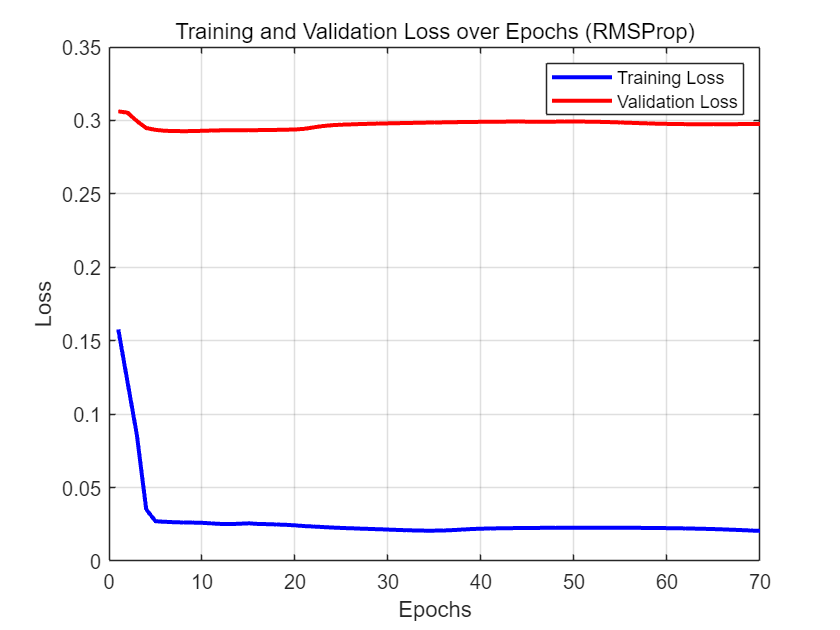

%% ----------------- Task 2 c) Handwritten forward + backward propagation (RMSProp Optimizer) -----------------
% Network architecture and training parameters
inputLayerSize = 4;      % number of input neurons (Iris has 4 features)
hiddenLayer1Size = 5;    % number of neurons in the first hidden layer
hiddenLayer2Size = 3;    % number of neurons in the second hidden layer
outputLayerSize = 3;     % number of output neurons (3 classes)
learningRate = 0.01;     % initial learning rate
epsilon = 1e-8;          % small constant to prevent division by zero
beta = 0.9;              % decay rate for RMSProp
epochs = 70;           % number of training iterations

% Randomly initialize weights and biases
W1 = randn(inputLayerSize, hiddenLayer1Size);
B1 = randn(1, hiddenLayer1Size);

W2 = randn(hiddenLayer1Size, hiddenLayer2Size);
B2 = randn(1, hiddenLayer2Size);

W3 = randn(hiddenLayer2Size, outputLayerSize);
B3 = randn(1, outputLayerSize);

% Initialize moving averages of squared gradients
S_W1 = zeros(size(W1));
S_B1 = zeros(size(B1));
S_W2 = zeros(size(W2));
S_B2 = zeros(size(B2));
S_W3 = zeros(size(W3));
S_B3 = zeros(size(B3));

% Define the activation function (tanh), its derivative, and softmax
tanhActivation = @(x) tanh(x);
dtanh = @(x) 1 - tanh(x).^2;
softmax = @(x) exp(x) ./ sum(exp(x)); % softmax along each row

% Arrays to store the loss values for both training and validation
loss_values = zeros(epochs, 1);
validation_loss_values = zeros(epochs, 1);
learning_rate_values = zeros(epochs, 1); % Store effective learning rate

%% Train the network (sample-by-sample update)
for epoch = 1:epochs
    total_train_loss = 0;     % accumulate training loss for averaging

    for i = 1:numTrainSamples
        %% Forward pass (single sample)
        x = trainData(i, :)';      % current sample features (column vector)
        y = trainLabels(i, :)';    % current sample one-hot label (column vector)
        
        % 1st hidden layer
        Z1 = W1' * x + B1';          % W1 is [4 x 5], so W1' is [5 x 4]
        A1 = tanhActivation(Z1);     % output shape [5 x 1]
        
        % 2nd hidden layer
        Z2 = W2' * A1 + B2';
        A2 = tanhActivation(Z2);     % output shape [3 x 1]
        
        % Output layer
        Z3 = W3' * A2 + B3';
        A3 = softmax(Z3);           % output shape [3 x 1]
        
        % Compute training loss (MSE for classification as an example)
        error = A3 - y;
        total_train_loss = total_train_loss + sum(error.^2) / numel(error);
        
        %% Backpropagation for gradient computation
        % Gradients in output layer
        dZ3 = error;                   % shape [3 x 1]
        dW3 = A2 * dZ3';               % shape [3 x 3] -> consistent with W3
        dB3 = dZ3;                     % shape [3 x 1]
        
        % Gradients in 2nd hidden layer
        dZ2 = (W3 * dZ3) .* dtanh(Z2); % shape [3 x 1]
        dW2 = A1 * dZ2';               % shape [5 x 3]
        dB2 = dZ2;                     % shape [3 x 1]
        
        % Gradients in 1st hidden layer
        dZ1 = (W2 * dZ2) .* dtanh(Z1); % shape [5 x 1]
        dW1 = x * dZ1';               % shape [4 x 5]
        dB1 = dZ1;                     % shape [5 x 1]
        
        %% RMSProp updates
        S_W1 = beta * S_W1 + (1 - beta) * (dW1.^2);
        S_B1 = beta * S_B1 + (1 - beta) * (dB1'.^2);
        
        S_W2 = beta * S_W2 + (1 - beta) * (dW2.^2);
        S_B2 = beta * S_B2 + (1 - beta) * (dB2'.^2);
        
        S_W3 = beta * S_W3 + (1 - beta) * (dW3.^2);
        S_B3 = beta * S_B3 + (1 - beta) * (dB3'.^2);
        
        W1 = W1 - (learningRate ./ (sqrt(S_W1) + epsilon)) .* dW1;
        B1 = B1 - (learningRate ./ (sqrt(S_B1) + epsilon)) .* dB1';
        
        W2 = W2 - (learningRate ./ (sqrt(S_W2) + epsilon)) .* dW2;
        B2 = B2 - (learningRate ./ (sqrt(S_B2) + epsilon)) .* dB2';
        
        W3 = W3 - (learningRate ./ (sqrt(S_W3) + epsilon)) .* dW3;
        B3 = B3 - (learningRate ./ (sqrt(S_B3) + epsilon)) .* dB3';
    end
    
    % Store the average training loss for this epoch
    loss_values(epoch) = total_train_loss / numTrainSamples;
    
    % Compute the effective learning rate for the first parameter of W1
    effective_learning_rate = learningRate / (sqrt(S_W1(1, 1)) + epsilon);
    learning_rate_values(epoch) = effective_learning_rate;

    %% Validation forward pass
    Z1_val = validationData * W1 + B1;   % shape [numValSamples x hiddenLayer1Size]
    A1_val = tanhActivation(Z1_val);

    Z2_val = A1_val * W2 + B2;          
    A2_val = tanhActivation(Z2_val);

    Z3_val = A2_val * W3 + B3;
    A3_val = softmax(Z3_val);

    % Compute validation loss (MSE)
    validation_error = A3_val - validationLabels;
    validation_loss = sum(validation_error(:).^2) / numel(validation_error);
    validation_loss_values(epoch) = validation_loss;
end

%% Plot the training and validation loss over epochs
figure;
plot(1:epochs, loss_values, '-b', 'LineWidth', 2);
hold on;
plot(1:epochs, validation_loss_values, '-r', 'LineWidth', 2);
xlabel('Epochs');
ylabel('Loss');
title('Training and Validation Loss over Epochs (RMSProp)');
legend('Training Loss', 'Validation Loss');
grid on;

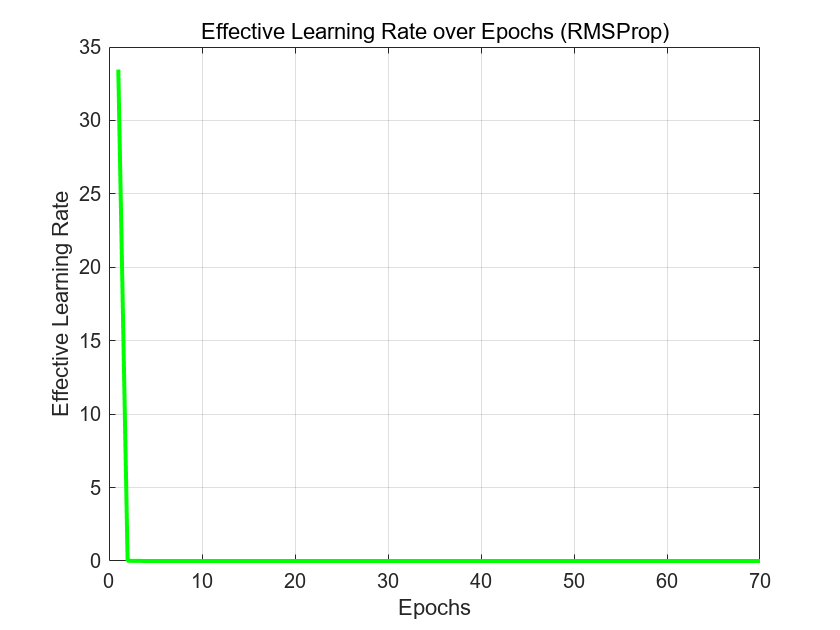


%% Plot the effective learning rate over epochs
figure;
plot(1:epochs, learning_rate_values, '-g', 'LineWidth', 2);
xlabel('Epochs');
ylabel('Effective Learning Rate');
title('Effective Learning Rate over Epochs (RMSProp)');
grid on;

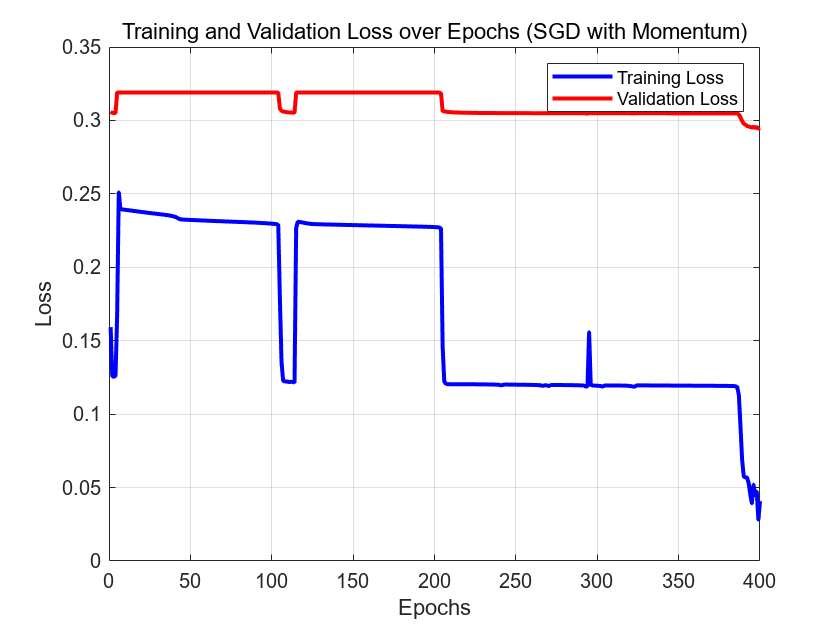

%% ----------------- Task 2 c) Handwritten forward + backward propagation (SGD with Momentum Optimizer) -----------------
% Network architecture and training parameters
inputLayerSize = 4;      % number of input neurons (Iris has 4 features)
hiddenLayer1Size = 5;    % number of neurons in the first hidden layer
hiddenLayer2Size = 3;    % number of neurons in the second hidden layer
outputLayerSize = 3;     % number of output neurons (3 classes)
initialLearningRate = 0.01; % initial learning rate
momentum = 0.9;          % momentum factor
epochs = 400;           % number of training iterations

% Randomly initialize weights and biases
W1 = randn(inputLayerSize, hiddenLayer1Size);
B1 = randn(1, hiddenLayer1Size);

W2 = randn(hiddenLayer1Size, hiddenLayer2Size);
B2 = randn(1, hiddenLayer2Size);

W3 = randn(hiddenLayer2Size, outputLayerSize);
B3 = randn(1, outputLayerSize);

% Initialize velocity terms for momentum
vW1 = zeros(size(W1));
vB1 = zeros(size(B1));

vW2 = zeros(size(W2));
vB2 = zeros(size(B2));

vW3 = zeros(size(W3));
vB3 = zeros(size(B3));

% Define the activation function (tanh), its derivative, and softmax
tanhActivation = @(x) tanh(x);
dtanh = @(x) 1 - tanh(x).^2;
softmax = @(x) exp(x) ./ sum(exp(x)); % softmax along each row

% Arrays to store the loss values and learning rates
loss_values = zeros(epochs, 1);
validation_loss_values = zeros(epochs, 1);
learning_rates = zeros(epochs, 1);

%% Train the network (sample-by-sample update with momentum)
for epoch = 1:epochs
    total_train_loss = 0;     % accumulate training loss for averaging

    % Adjust learning rate dynamically
    learningRate = initialLearningRate / (1 + 0.01 * epoch);
    learning_rates(epoch) = learningRate;

    for i = 1:numTrainSamples
        %% Forward pass (single sample)
        x = trainData(i, :)';      % current sample features (column vector)
        y = trainLabels(i, :)';    % current sample one-hot label (column vector)
        
        % 1st hidden layer
        Z1 = W1' * x + B1';          % W1 is [4 x 5], so W1' is [5 x 4]
        A1 = tanhActivation(Z1);     % output shape [5 x 1]
        
        % 2nd hidden layer
        Z2 = W2' * A1 + B2';
        A2 = tanhActivation(Z2);     % output shape [3 x 1]
        
        % Output layer
        Z3 = W3' * A2 + B3';
        A3 = softmax(Z3);           % output shape [3 x 1]
        
        % Compute training loss (MSE for classification as an example)
        error = A3 - y;
        total_train_loss = total_train_loss + sum(error.^2) / numel(error);
        
        %% Backpropagation for gradient computation
        % Gradients in output layer
        dZ3 = error;                   % shape [3 x 1]
        dW3 = A2 * dZ3';               % shape [3 x 3] -> consistent with W3
        dB3 = dZ3;                     % shape [3 x 1]
        
        % Gradients in 2nd hidden layer
        dZ2 = (W3 * dZ3) .* dtanh(Z2); % shape [3 x 1]
        dW2 = A1 * dZ2';               % shape [5 x 3]
        dB2 = dZ2;                     % shape [3 x 1]
        
        % Gradients in 1st hidden layer
        dZ1 = (W2 * dZ2) .* dtanh(Z1); % shape [5 x 1]
        dW1 = x * dZ1';               % shape [4 x 5]
        dB1 = dZ1;                     % shape [5 x 1]
        
        % Update weights and biases (SGD with Momentum)
        vW1 = momentum * vW1 - learningRate * dW1;
        vB1 = momentum * vB1 - learningRate * dB1';
        W1 = W1 + vW1;
        B1 = B1 + vB1;
        
        vW2 = momentum * vW2 - learningRate * dW2;
        vB2 = momentum * vB2 - learningRate * dB2';
        W2 = W2 + vW2;
        B2 = B2 + vB2;
        
        vW3 = momentum * vW3 - learningRate * dW3;
        vB3 = momentum * vB3 - learningRate * dB3';
        W3 = W3 + vW3;
        B3 = B3 + vB3;
    end
    
    % Store the average training loss for this epoch
    loss_values(epoch) = total_train_loss / numTrainSamples;
    
    %% Validation forward pass
    Z1_val = validationData * W1 + B1;   % shape [numValSamples x hiddenLayer1Size]
    A1_val = tanhActivation(Z1_val);

    Z2_val = A1_val * W2 + B2;          
    A2_val = tanhActivation(Z2_val);

    Z3_val = A2_val * W3 + B3;
    A3_val = softmax(Z3_val);

    % Compute validation loss (MSE)
    validation_error = A3_val - validationLabels;
    validation_loss = sum(validation_error(:).^2) / numel(validation_error);
    validation_loss_values(epoch) = validation_loss;
end

%% Plot the training and validation loss over epochs
figure;
plot(1:epochs, loss_values, '-b', 'LineWidth', 2);
hold on;
plot(1:epochs, validation_loss_values, '-r', 'LineWidth', 2);
xlabel('Epochs');
ylabel('Loss');
title('Training and Validation Loss over Epochs (SGD with Momentum)');
legend('Training Loss', 'Validation Loss');
grid on;

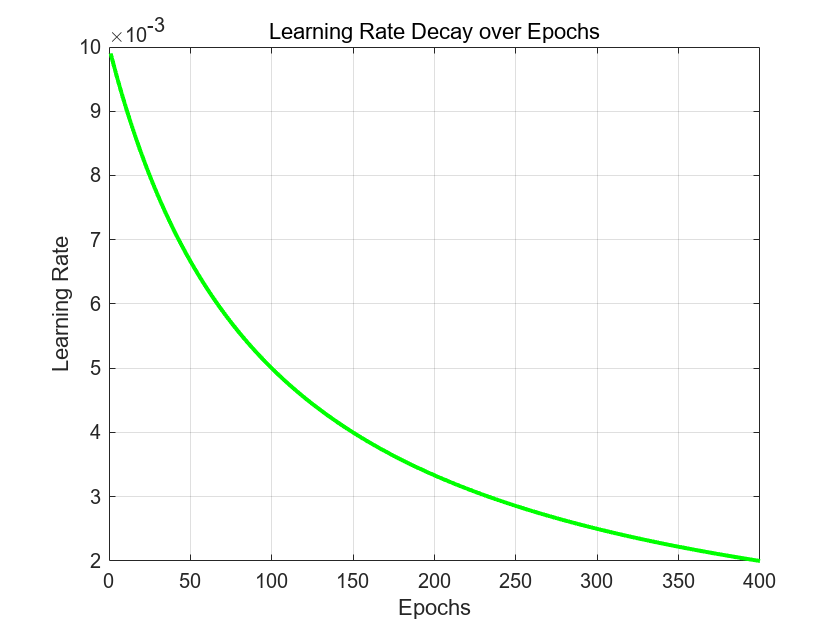


%% Plot the learning rate over epochs
figure;
plot(1:epochs, learning_rates, '-g', 'LineWidth', 2);
xlabel('Epochs');
ylabel('Learning Rate');
title('Learning Rate Decay over Epochs');
grid on;


%% Validation: make predictions and calculate accuracy
Z1_val = validationData * W1 + B1;
A1_val = tanhActivation(Z1_val);

Z2_val = A1_val * W2 + B2;
A2_val = tanhActivation(Z2_val);

Z3_val = A2_val * W3 + B3;
A3_val = softmax(Z3_val);

% Convert one-hot predictions to class indices
[~, predictedLabels] = max(A3_val, [], 2);
[~, actualLabels] = max(validationLabels, [], 2);
correct = sum(predictedLabels == actualLabels);
accuracy = (correct / size(validationData, 1)) * 100;
fprintf('Validation Accuracy: %.2f%%\n', accuracy);

Validation Accuracy: 95.56%



% Print the confusion matrix
confusionMat = confusionmat(actualLabels, predictedLabels);
disp('Confusion Matrix (SGD with Momentum):');

Confusion Matrix (SGD with Momentum):


disp(confusionMat);

    19     0     0
     0    11     2
     0     0    13



%% ----------------- Task 2 d) Using the MATLAB Toolbox -----------------
% Create a feedforward network 
net = feedforwardnet([5,3]);

% Set activation functions and training function
net.layers{1}.transferFcn = 'tansig'; 
net.layers{2}.transferFcn = 'tansig'; 
net.layers{3}.transferFcn = 'softmax'; % softmax for the output layer
net.trainFcn = 'traingd';              % use gradient descent

% Training parameters
net.trainParam.show = 2000;    % display training progress every 2000 epochs
net.trainParam.lr = 0.01;      % learning rate
net.trainParam.epochs = 40000; % maximum epochs
net.trainParam.goal = 1e-4;    % desired goal for training error
net.trainParam.max_fail = 100000; % Disable early stopping


% Train the network
[net, tr] = train(net, trainData', trainLabels');

% Extract validation loss from training record
validationLosses1 = tr.vperf;

% Plot validation loss over epochs
figure;
plot(tr.epoch, validationLosses1, '-r', 'LineWidth', 2);
xlabel('Epochs');
ylabel('Validation Loss');
title('Validation Loss Over Epochs');
grid on;

% Predict using validation data
net_output = sim(net, validationData');

% Convert the actual and predicted outputs to class indices
validationLabels = validationLabels';
[p, q] = size(validationLabels);
idx_Actual = zeros(1, q);
idx_Predicted = zeros(1, q);

for j = 1:q
    [~, idx_Actual(j)] = max(validationLabels(:, j));
    [~, idx_Predicted(j)] = max(net_output(:, j));
end


% Plot actual vs. predicted
figure;
plot(idx_Actual, 'b-', 'LineWidth', 1.5);
hold on;
plot(idx_Predicted, 'r-', 'LineWidth', 1.5);
hold off;
legend('Actual', 'Predicted');
title('Actual vs Predicted Classification');

% Plot the absolute error
figure;
plot(abs(idx_Actual - idx_Predicted), 'ro');
title('Prediction Error');

% Confusion matrix
confMat = confusionmat(idx_Actual, idx_Predicted);
disp('Confusion Matrix:');
disp(confMat);

% A nicer visualization of confusion matrix
% figure;
% confusionchart(idx_Actual, idx_Predicted);
% title('Confusion Matrix for Validation Data');

% Compute precision for each class
precision = diag(confMat) ./ sum(confMat, 2);
disp('Precision for each class:');
disp(precision);

% Compute overall accuracy
overallAccuracy = sum(idx_Actual == idx_Predicted) / q * 100;
fprintf('Overall Accuracy: %.2f%%\n', overallAccuracy);
